clear
clc
format shortG


## PROPIEDADES DEL SISTEMA

% definir matriz de masa
M = [[2,0];  %PISO 1
    [0,2]]   %PISO 2

M =      2     0
     0     2



% Definir matriz de rigidez
K=[[16,-8];  %PISO 1
    [-8,16]] %PISO 2

K =     16    -8
    -8    16




syms w lambda
det(-w^2*M+K);
w2=solve(det(-lambda*M+K)==0,lambda);
w2=sortrows(sort(w2,2));
w=round(sqrt(w2),2) %frecuencias

$$w = \left(\begin{array}{c} 2.0\\ 3.46 \end{array}\right)$$

## CALCULO MODOS

syms phi11 phi21 phi12 phi22
phi11=1;
eq1 = (K-w2(1)*M)*[phi11;phi21]==0;
phi21=solve(eq1(1),phi21);
phi1=round([phi11;phi21],2);
phi12=1;
eq2 = (K-w2(2)*M)*[phi12;phi22]==0;
phi22=solve(eq2(1),phi22);
phi2=round([phi12;phi22],2);
% MODOS DE VIBRAR
phi=[phi1,phi2] 

$$phi = \left(\begin{array}{cc} 1.0 & 1.0\\ 1.0 & -1.0 \end{array}\right)$$

## REPRESENTACIÓN DE LOS MODOS

modo1=[0,phi1(1),phi1(2)];
modo2=[0,phi2(1),phi2(2)];
gdl=[0,1,2];

tiledlayout(1,2)
nexttile
title('MODO 1')
hold on
line(modo1,gdl,'Color','red')
scatter(modo1,gdl)
% axis tight
xline(0,'--')
axis tight
ylim([0 2])
yticks([0 1 2])
box on
grid on
hold off

nexttile
hold on
title('MODO 2')
line(modo2,gdl,'Color','red')
scatter(modo2,gdl)
% axis tight
xline(0,'--')
axis tight
ylim([0 2])
yticks([0 1 2])
box on
grid on
hold off

## CONDICIONES INICIALES

u_i=[1;0]

u_i =      1
     0


v_i=[0;1]

v_i =      0
     1


## DETERMINAR CONSTANTES

syms A1 B1 A2 B2 t
Y1(t)=A1*cos(w(1)*t)+B1*sin(w(1)*t)

$$Y1(t) = A_{1}\,\cos\left(2.0\,t\right)+B_{1}\,\sin\left(2.0\,t\right)$$

Y2(t)=A2*cos(w(2)*t)+B2*sin(w(2)*t)

$$Y2(t) = A_{2}\,\cos\left(3.46\,t\right)+B_{2}\,\sin\left(3.46\,t\right)$$

u(t)=phi1*Y1(t)+phi2*Y2(t)

$$u(t) = \left(\begin{array}{c} 1.0\,A_{1}\,\cos\left(2.0\,t\right)+1.0\,B_{1}\,\sin\left(2.0\,t\right)+1.0\,A_{2}\,\cos\left(3.46\,t\right)+1.0\,B_{2}\,\sin\left(3.46\,t\right)\\ 1.0\,A_{1}\,\cos\left(2.0\,t\right)+1.0\,B_{1}\,\sin\left(2.0\,t\right)-1.0\,A_{2}\,\cos\left(3.46\,t\right)-1.0\,B_{2}\,\sin\left(3.46\,t\right) \end{array}\right)$$

v(t)=diff(u,t)

$$v(t) = \left(\begin{array}{c} 2.0\,B_{1}\,\cos\left(2.0\,t\right)-2.0\,A_{1}\,\sin\left(2.0\,t\right)+3.46\,B_{2}\,\cos\left(3.46\,t\right)-3.46\,A_{2}\,\sin\left(3.46\,t\right)\\ 2.0\,B_{1}\,\cos\left(2.0\,t\right)-2.0\,A_{1}\,\sin\left(2.0\,t\right)-3.46\,B_{2}\,\cos\left(3.46\,t\right)+3.46\,A_{2}\,\sin\left(3.46\,t\right) \end{array}\right)$$

cond_borde1=u(0)==u_i

$$cond\_borde1 = \left(\begin{array}{c} 1.0\,A_{1}+1.0\,A_{2}=1\\ 1.0\,A_{1}-1.0\,A_{2}=0 \end{array}\right)$$

cond_borde2=v(0)==v_i

$$cond\_borde2 = \left(\begin{array}{c} 2.0\,B_{1}+3.46\,B_{2}=0\\ 2.0\,B_{1}-3.46\,B_{2}=1 \end{array}\right)$$

[A1,A2]=solve(cond_borde1,{A1,A2})

$$A1 = 0.5$$

$$A2 = 0.5$$

[B1,B2]=solve(cond_borde2,{B1,B2})

$$B1 = 0.25$$

$$B2 = -0.1445086705202312138728323699422$$

## FUNCION DESPLAZAMIENTO Y VELOCIDAD

u=matlabFunction(u(t));
v=matlabFunction(v(t));
desplazamiento=u(A1,A2,B1,B2,t);
velocidad=v(A1,A2,B1,B2,t);


## VERIFICACION DE LAS CONDICIONES DE BORDE    

% si son iguales, los coeficientes de la función cumplen las condiciones de borde iniciales
u(A1,A2,B1,B2,0)==u_i

$$ans = \left(\begin{array}{c} 1.0=1.0\\ 0=0 \end{array}\right)$$

v(A1,A2,B1,B2,0)==v_i

$$ans = \left(\begin{array}{c} 0=0\\ 1.0=1.0 \end{array}\right)$$

## DESPLAZAMIENTO EN t 

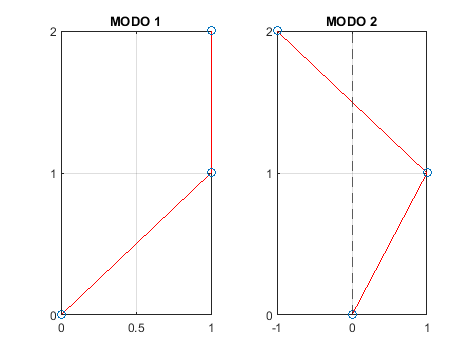

figure; 
% hold on
title('DOS PISOS')
xlabel('Desplazamiento (m)')
ylabel('Pisos')


xline(0,'--')
for t=0.00001:0.1:10; 
desplazamiento=round(u(A1,A2,B1,B2,t),2);
velocidad=round(v(A1,A2,B1,B2,t),2);
puntos1=[0,desplazamiento(1),desplazamiento(2)];
gdl=[0,1,2];
title('DESPLAZAMIENTO (m)')
hold on
line(puntos1,gdl,'Color','b','LineStyle','-','Marker','x','MarkerEdgeColor','g')
% scatter(puntos1,gdl,[],'filled')

xline(0,'--')
xlim([-2 2])
xticks([-2 -1 0 1 2])
ylim([0 2])
yticks([0 1 2])
box on
grid on
 drawnow limitrate
 
end

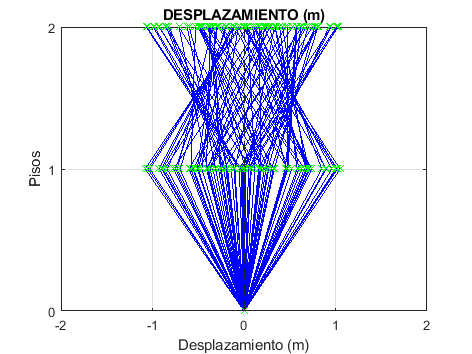

hold off